lenna = imread("lenna_png.png")

lenna = 512×512×3 uint8 array
lenna(:,:,1) =

   226   226   223   223   226   226   228   227   227   225   228   225   223   226   223   221   221   221   222   222   223   223   224   221   218   221   223   225   221   221   220   223   225   223   226   223   225   227   229   231   231   232   230   233   234   237   233   231   237   238   234   235   234   232   233   230   227   221   219   213   203   202   187   174   169   166   158   153   155   157   166   161   166   165   169   170   174   174   175   180   177   178   177   177   175   175   173   179   177   178   177   178   182   178   178   179   176   179   178   174   173   174   179   180   177   182   182   185   187   190   194   194   190   199   195   193   195   196   192   201   203   202   206   197   201   205   202   206   205   207   209   203   204   205   202   204   200   206   204   206   207   204   203   206   205   207   203   201   202   203   204   202   205   201   204   202   205   207   206

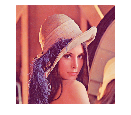

imshow(lenna)

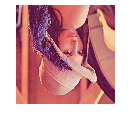


% flip image
imshow(flipud(lenna))

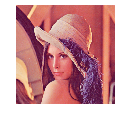

imshow(fliplr(lenna))

## RGB channels

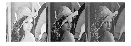

imshow(lenna(:,:));

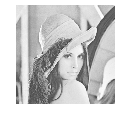

imshow(lenna(:,:,1));title("red");

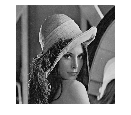

imshow(lenna(:,:,2));title("blue");

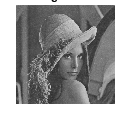

imshow(lenna(:,:,3));title("green");

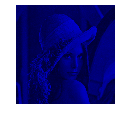


% blue channel:
blue = lenna;
blue(:,:,1) = 0;
blue(:,:,2) = 0;
imshow(blue);

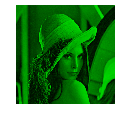


% green channel:
green = lenna;
green(:,:,1) = 0;
green(:,:,3) = 0;
imshow(green);

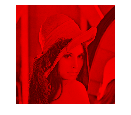


% red channel:
red = lenna;
red(:,:,2) = 0;
red(:,:,3) = 0;
imshow(red);

## Blurring images - convolution

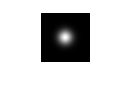

H = my_gaussian(100,10);
imshow(H)

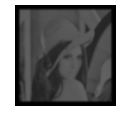


imshow(conv2(lenna(:,:,1),my_gaussian(50,5)/100000))

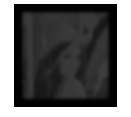


H2 = fspecial('gaussian',100,10);
imshow(conv2(lenna(:,:,1),H2/1000))

## Edge Detection

help edge

 edge Find edges in intensity image.
    edge takes an intensity or a binary image I as its input, and returns a
    binary image BW of the same size as I, with 1's where the function
    finds edges in I and 0's elsewhere.
 
    edge supports six different edge-finding methods:
 
       The Sobel method finds edges using the Sobel approximation to the
       derivative. It returns edges at those points where the gradient of
       I is maximum.
 
       The Prewitt method finds edges using the Prewitt approximation to
       the derivative. It returns edges at those points where the gradient
       of I is maximum.
 
       The Roberts method finds edges using the Roberts approximation to
       the derivative. It returns edges at those points where the gradient
       of I is maximum.
 
       The Laplacian of Gaussian method finds edges by looking for zero
       crossings after filtering I with a Laplacian of Gaussian filter.
 
   

E = edge(lenna(:,:,1))

E = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

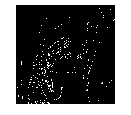

imshow(E)